tic

% Φόρτωση και Επισκόπηση του Dataset
disp("Φόρτωση του dataset.")

Φόρτωση του dataset.


T = readtable('seven_wonders_reviews.xlsx', 'TextType', 'string');
head(T)

          user          rating                                                                                                                                                                                                                                                                                                                                                                                                         comment                                                                                                                                                                                                                                                                                                                                                                                                     
    ________________    ______    _____________________________________________________

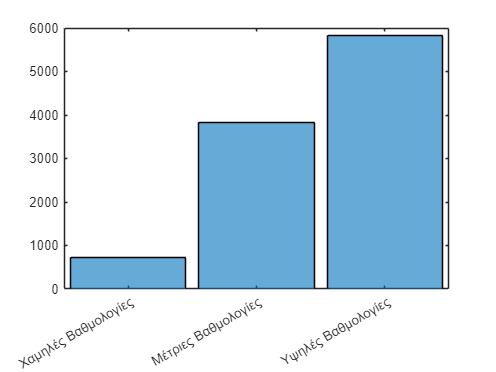


new_reviews = [
    "7 Wonders is an exceptional game that brilliantly captures the thrill of civilization building. The drafting mechanic keeps all players engaged, and the diverse strategies make each game unique. With beautiful artwork and well-designed components, it’s a visual treat as well. It’s a perfect choice for both casual and serious gamers looking to have a great time together."
    "While 7 Wonders has its fans, I found it somewhat underwhelming. The game can feel a bit repetitive after a few plays, as the strategies can become predictable. Additionally, the scoring system can be confusing for new players, leading to a frustrating experience. It’s not the engaging civilization-building game I hoped it would be."
    "7 Wonders is a game with great potential, showcasing fantastic artwork and an engaging premise. The drafting mechanism is fun and encourages interaction among players. However, I felt that the learning curve can be steep for newcomers, which might hinder the enjoyment for some. Overall, it’s a solid game with its highs and lows, making it worth a try for those who appreciate strategic gameplay."];

categoricalRatings = strings(size(T.rating));
categoricalRatings(T.rating >= 1 & T.rating <= 5) = "Χαμηλές Βαθμολογίες";
categoricalRatings(T.rating >= 5.1 & T.rating <= 7.9) = "Μέτριες Βαθμολογίες";
categoricalRatings(T.rating >= 8 & T.rating <= 10) = "Υψηλές Βαθμολογίες";
categoricalRatings = categorical(categoricalRatings, ...
    ["Χαμηλές Βαθμολογίες", "Μέτριες Βαθμολογίες", "Υψηλές Βαθμολογίες"]);

% Οπτικοποίηση της κατανομής των βαθμολογιών
figure(1)
histogram(categoricalRatings)

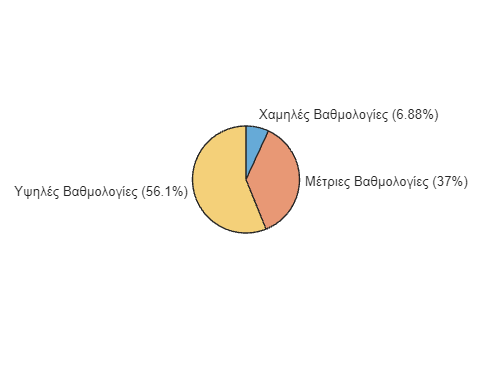

figure(2)
piechart(categoricalRatings)

% Προεπεξεργασία Σχολίων και Δημιουργία Αρχικού Word Cloud

disp("Εκτέλεση προεπεξεργασίας για την απομάκρυνση θορύβου και δημιουργία ενός αρχικού word cloud για τα σχόλια.")
[preprocessedText] = text_preprocessing(T.comment);

% Προβολή Λεπτομερειών Τοκενς και Εμφάνιση Word Cloud
disp("Λεπτομέρειες tokens των επεξεργασμένων σχολίων:")
tokenDetails(preprocessedText);
wordcloud(preprocessedText);
title("Word Cloud μετά την προεπεξεργασία")

% Χρήση ενός Απλού Εποπτευόμενου Ταξινομητή για Εκτίμηση Βαθμολογίας
disp("Χρήση ενός απλού εποπτευόμενου ταξινομητή για εκτίμηση της βαθμολογίας νέων κριτικών.")
new_reviews = [
    "7 Wonders is an exceptional game that brilliantly captures the thrill of civilization building. The drafting mechanic keeps all players engaged, and the diverse strategies make each game unique. With beautiful artwork and well-designed components, it’s a visual treat as well. It’s a perfect choice for both casual and serious gamers looking to have a great time together."
    "While 7 Wonders has its fans, I found it somewhat underwhelming. The game can feel a bit repetitive after a few plays, as the strategies can become predictable. Additionally, the scoring system can be confusing for new players, leading to a frustrating experience. It’s not the engaging civilization-building game I hoped it would be."
    "7 Wonders is not a great game. I felt that the learning curve can be steep for newcomers, which might hinder the enjoyment for some. Overall, in my opinion, it is not a game for those who don't want to think very much."];
[acc_SC] = simple_SC(T, new_reviews);

% Εκτέλεση ταξινόμησης με embeddings για Hold-Out και Cross-Validation
disp("Εκτέλεση ταξινόμησης με embeddings σε Hold-Out και Cross-Validation για την εύρεση του καλύτερου ταξινομητή.")
[holdoutAccuracies, crossvalAccuracies] = classification_with_embeddings(T);

% Ταξινομητής με Embeddings Εγγράφων
disp("Χρήση ταξινομητή με embeddings εγγράφων για καλύτερη ανάλυση των σχολίων.")
[acc_DE_linear, acc_DE_rbf, categoryCounts] = doc_embeddings(T);

% Εκτύπωση Word Clouds για κάθε κατηγορία βαθμολόγησης
disp("Εκτύπωση Word Clouds για κάθε κατηγορία βαθμολόγησης.")
[toplow, topmed, tophigh] = multiword_phrases(T);
disp("Top 10 φράσεις στις χαμηλές βαθμολογίες.")
disp(toplow)
disp("Top 10 φράσεις στις μέτριες βαθμολογίες.")
disp(topmed)
disp("Top 10 φράσεις στις υψηλές βαθμολογίες.")
disp(tophigh)

## LDA

% Προσδιορισμός του βέλτιστου solver για το LDA
disp("Προσδιορισμός του βέλτιστου solver για το LDA με χρήση της συνάρτησης lda_solvers_comp.")
lda_solvers_comp(T.comment);

% Προσδιορισμός του βέλτιστου αριθμού θεμάτων για το LDA με Hold Out
disp("Προσδιορισμός του βέλτιστου αριθμού θεμάτων για το LDA με χρήση της συνάρτησης nof_topics_lda.")
[results] = nof_topics_lda(T.comment);

% Προσδιορισμός του βέλτιστου αριθμού θεμάτων για το LDA με Cross Validation
disp("Προσδιορισμός του βέλτιστου αριθμού θεμάτων για το LDA με χρήση της συνάρτησης nof_topics_lda_cv.")
[results_cv] = nof_topics_lda_cv(T.comment);

% Προβολή Πιθανότητας Θεμάτων για Νέα Σχόλια σε LDA
disp("Ανάλυση θεμάτων για νέα σχόλια χρησιμοποιώντας το εκπαιδευμένο μοντέλο LDA.")
new_reviews = [
    "7 Wonders is an exceptional game that brilliantly captures the thrill of civilization building. The drafting mechanic keeps all players engaged, and the diverse strategies make each game unique. With beautiful artwork and well-designed components, it’s a visual treat as well. It’s a perfect choice for both casual and serious gamers looking to have a great time together."
    "While 7 Wonders has its fans, I found it somewhat underwhelming. The game can feel a bit repetitive after a few plays, as the strategies can become predictable. Additionally, the scoring system can be confusing for new players, leading to a frustrating experience. It’s not the engaging civilization-building game I hoped it would be."
    "7 Wonders is a game with great potential, showcasing fantastic artwork and an engaging premise. The drafting mechanism is fun and encourages interaction among players. However, I felt that the learning curve can be steep for newcomers, which might hinder the enjoyment for some. Overall, it’s a solid game with its highs and lows, making it worth a try for those who appreciate strategic gameplay."];
[tbl,top] = my_lda(T.comment, new_reviews);
disp("Οι κορυφαίες λέξεις ανά θέμα για τις νέες κριτικές έχουν ως εξής:")
disp(top)

## BERT


Βαθμολογίες:
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10

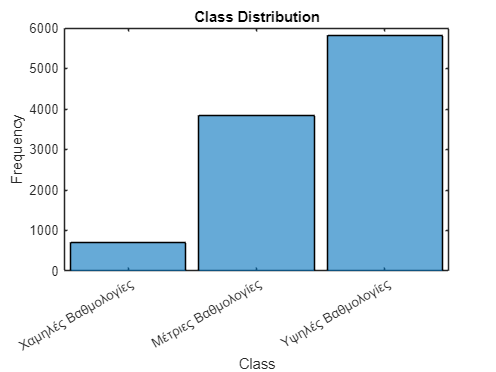

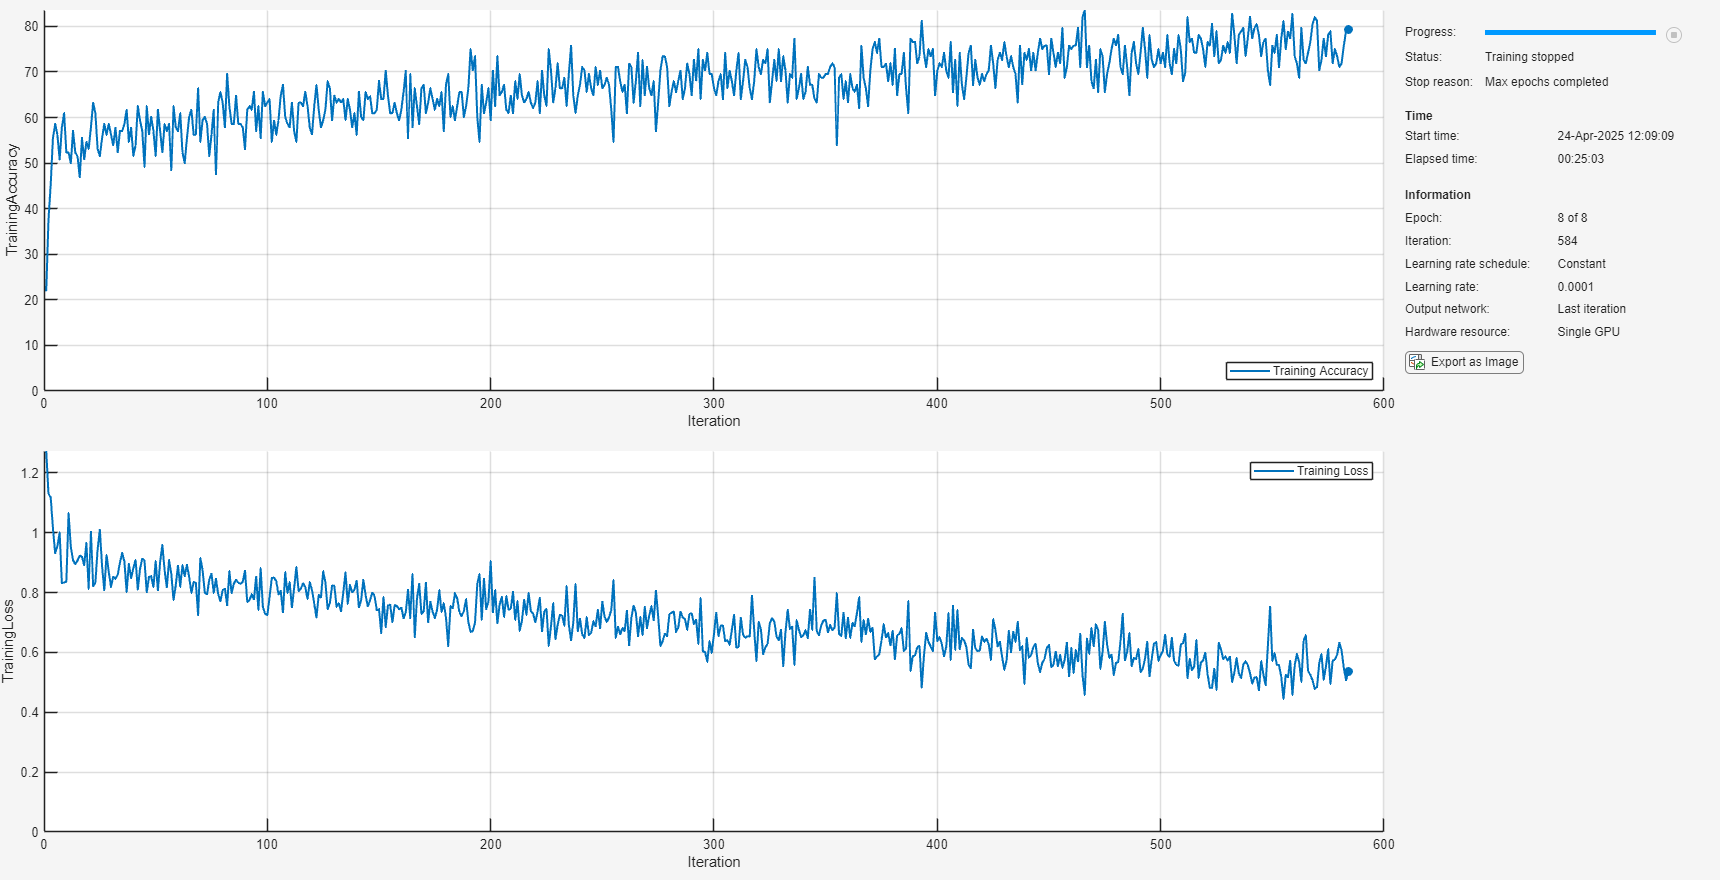

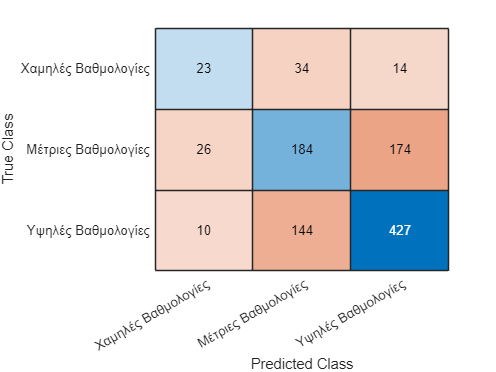


Accuracy: 0.61
Precision per class:
    0.3898    0.5083    0.6943

Recall per class:
    0.3239    0.4792    0.7349

F1-score per class:
    0.3538    0.4933    0.7140



[tiny_bert_accuracy, tiny_bert_precision, tiny_bert_recall, tiny_bert_f1_score] = tiny_bert(T, new_reviews);


Βαθμολογίες:
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10

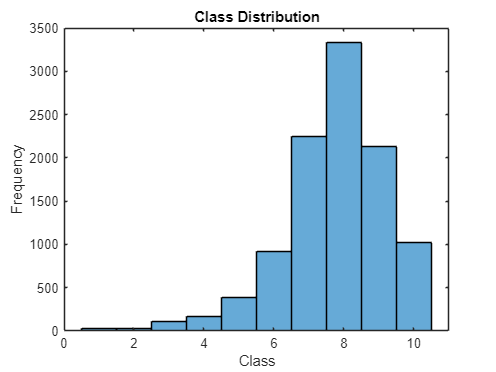

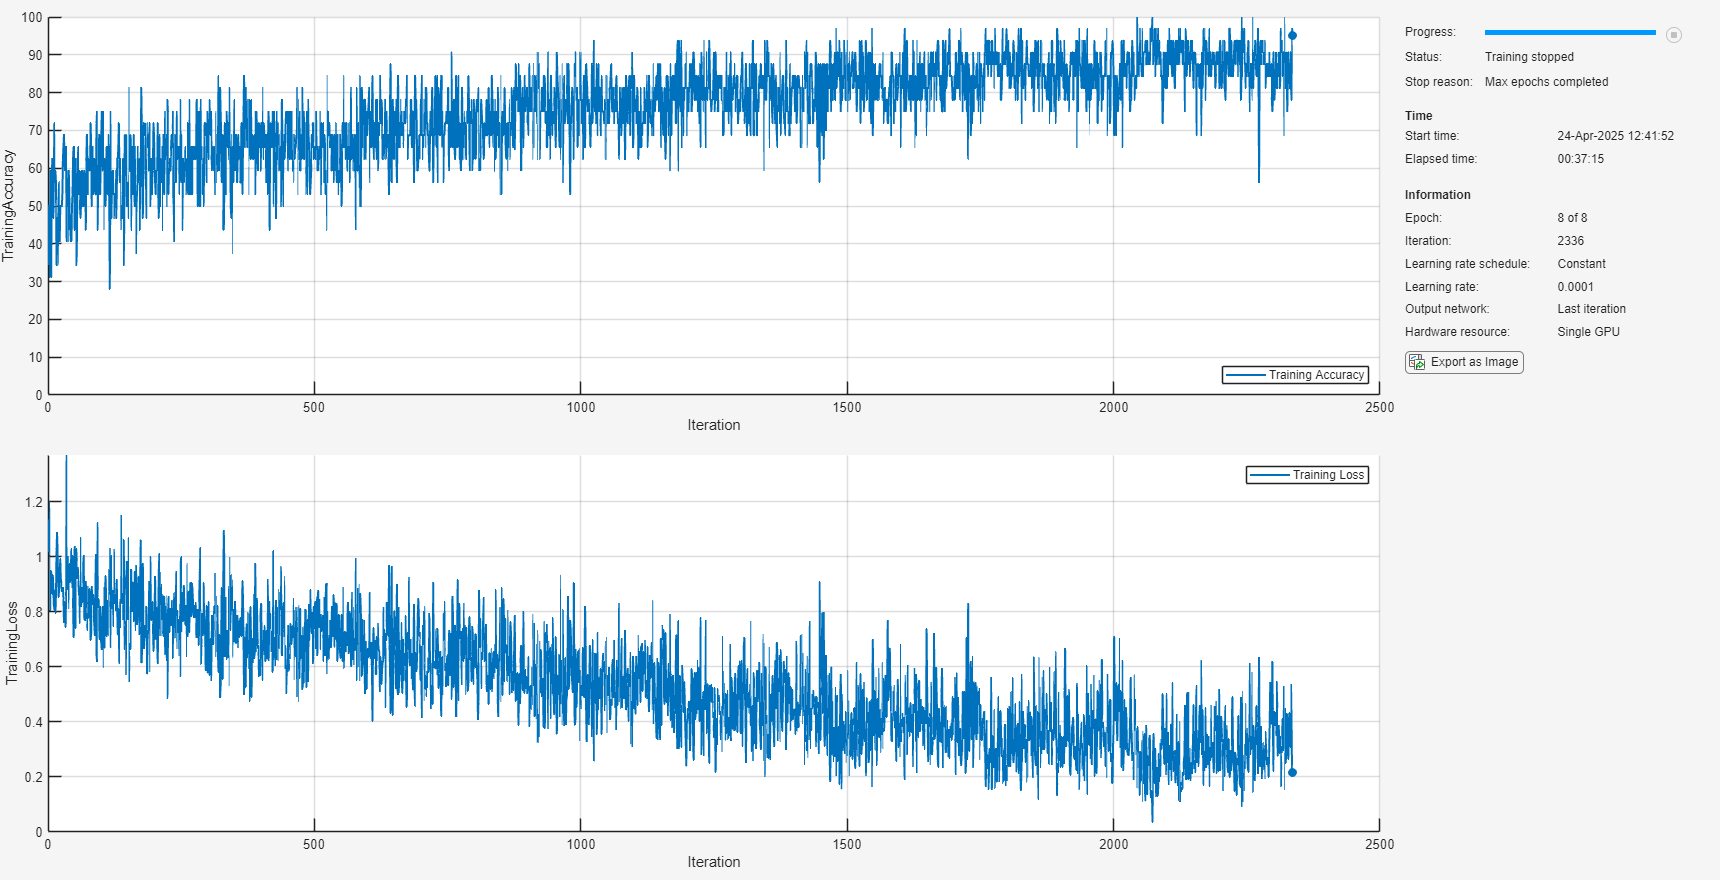

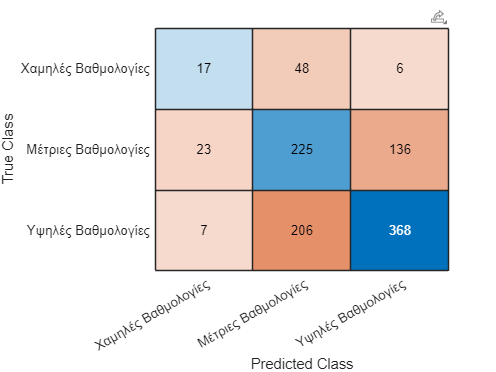


Accuracy: 0.59
Precision per class:
    0.3617    0.4697    0.7216

Recall per class:
    0.2394    0.5859    0.6334

F1-score per class:
    0.2881    0.5214    0.6746



[mini_bert_accuracy, mini_bert_precision, mini_bert_recall, mini_bert_f1_score] = mini_bert(T, new_reviews);


Βαθμολογίες:
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10
    10

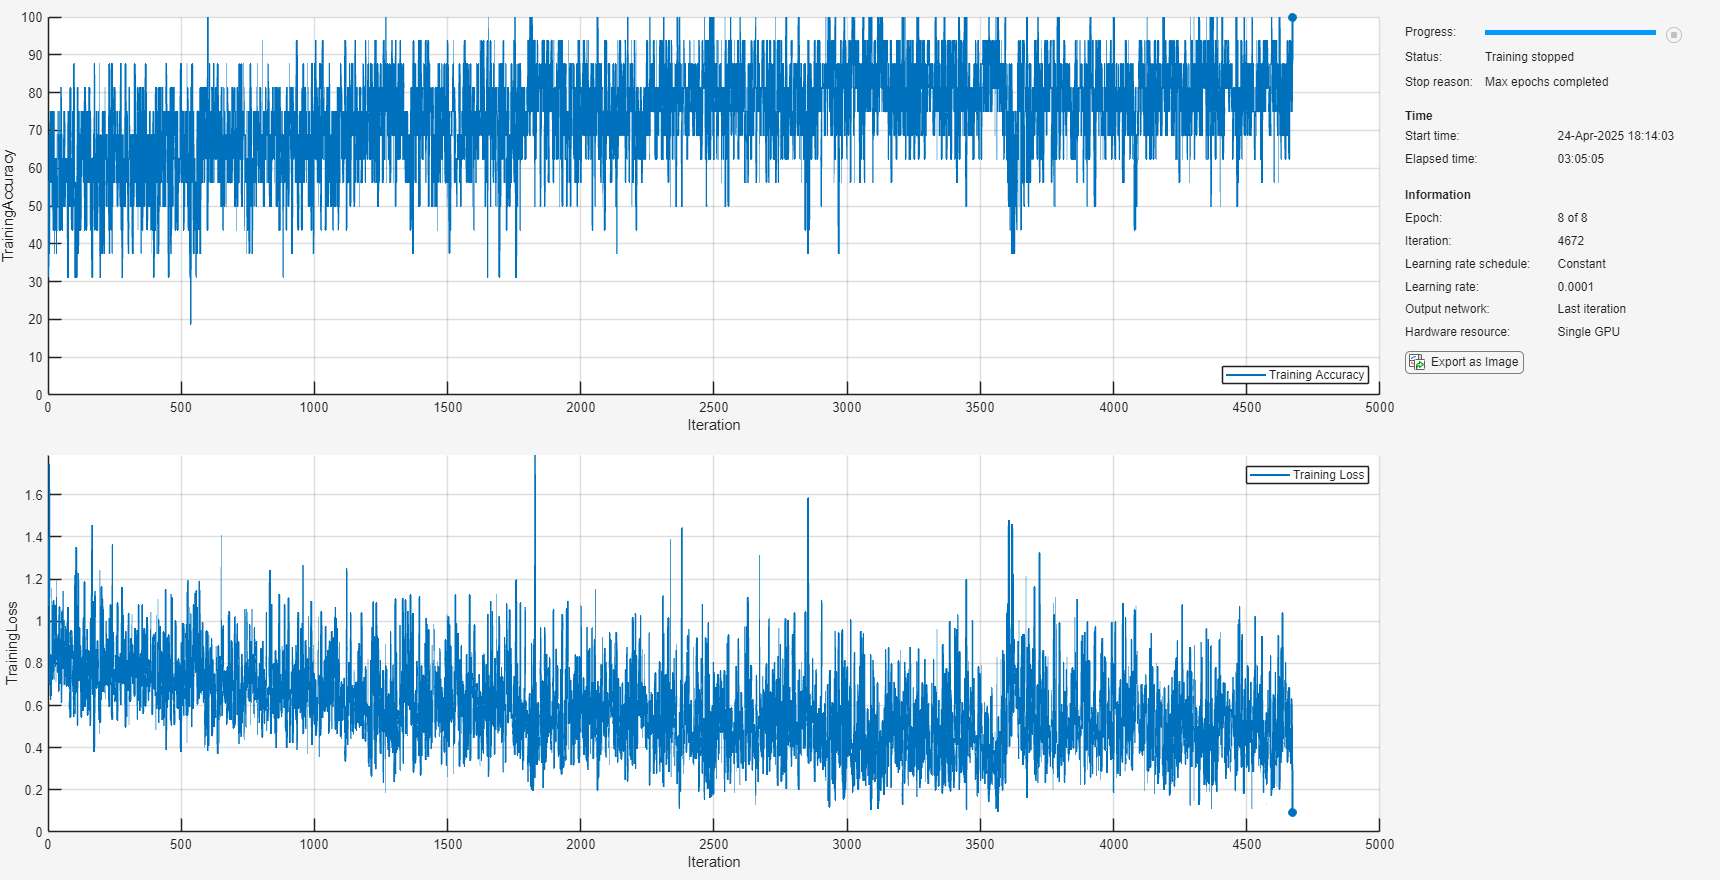

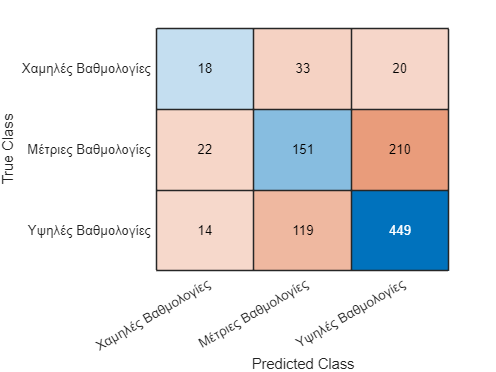


Accuracy: 0.60
Precision per class:
    0.3333    0.4983    0.6613

Recall per class:
    0.2535    0.3943    0.7715

F1-score per class:
    0.2880    0.4402    0.7121



[small_bert_accuracy, small_bert_precision, small_bert_recall, small_bert_f1_score] = small_bert(T, new_reviews);

## SENTIMENT ANALYSIS

[compoundScores, tbl] = darth_vader(T.comment);

[compoundScores, lexiconTable, testDataResults] = darth_vader_train_test(T);

[compoundScores, lexiconTable, testDataResults] = compare_sentiment_models(T);

toc